Name: Yusu (Cosmo) Zhao

Student Number: 20761282

PartA:

 1. 

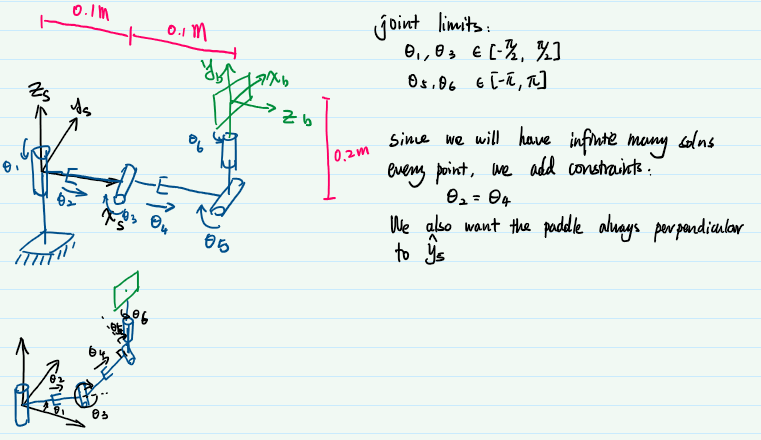

The deverivation is as follows:

First of all, the joint 1 and joint 6 are always rotating about z-axis, and they are the only joints that rotates about the z-axis, therefore, they are responsible for controlling the contact angle alpha. Joint 1 rotates the arm, and joint 6 compensate that rotation to adjust the paddel to have the contact angle alpha. Therefore, $\theta {\;}_1 +\theta {\;}_6 =\alpha \;$

Then we claim that $\theta {\;}_3 +\theta {\;}_5 =0\;$. This is because that we need to make the last link perpendicular to the x-y plane so that the paddle is perpendicular to the ground. Joint 3 can be seen as used to lift up/down the paddle, and joint 5 is to compensate the lifting.

If we hold those conditions above, then we can assume that the end effctor coordinate p_z can be used to calculate theta_3. There can be two configurations for "elbow up" and "elbow down", where "elbow up" refers to the configuration that the end effctor is higher than the joint 5 (higher means positive in z-axis), so $\sin \;\theta {\;}_3 =\frac{-p_z \pm 0\ldotp 2}{0\ldotp 1+\theta {\;}_4 }$. When elbow up, we use +0.2.

Then we project the arm to the xy-plane. The length of this projection can be represented as two parts. The first part is L_1, since the first link always stay on the xy-plane. The second part is $L_2 \;\cos \;\theta {\;}_3$ since the link is lifted by joint 3. This lengths also equals to $\sqrt{\left(p_{x\;}^{2\;} +p_{y\;}^2 \right)}$. Therefore, we can get an equation, and simplify it to obtain: $L_1^2 +L_2^{2\;} \cos^{2\;} \theta {\;}_3 +2L_1 L_{2\;} \cos \theta {\;}^3 =p_{x\;}^{2\;} +p_{y\;}^2$

With the constraints above, $\theta_2 =\theta {\;}_4$, we have $L_1 =L_2$. We use r to denote L_1 and L_2 , and use d to denote theta_2 and theta_4.So the equation can be further simplified, and we solve for $\sin \theta_3 =-1+\sqrt{\;\frac{p_x^2 +p_y^{2\;} }{r^2 }}$

Then, we can use the property that $\sin^2 \theta +\cos^{2\;} \theta =1$ to solve r, which also solves d. Again, $d=\theta {\;}_2 =\theta {\;}_4$. Then we can use theta_4 to calculate theta_3.

Finally, theta1 is a funciton of p_y and p_x. 

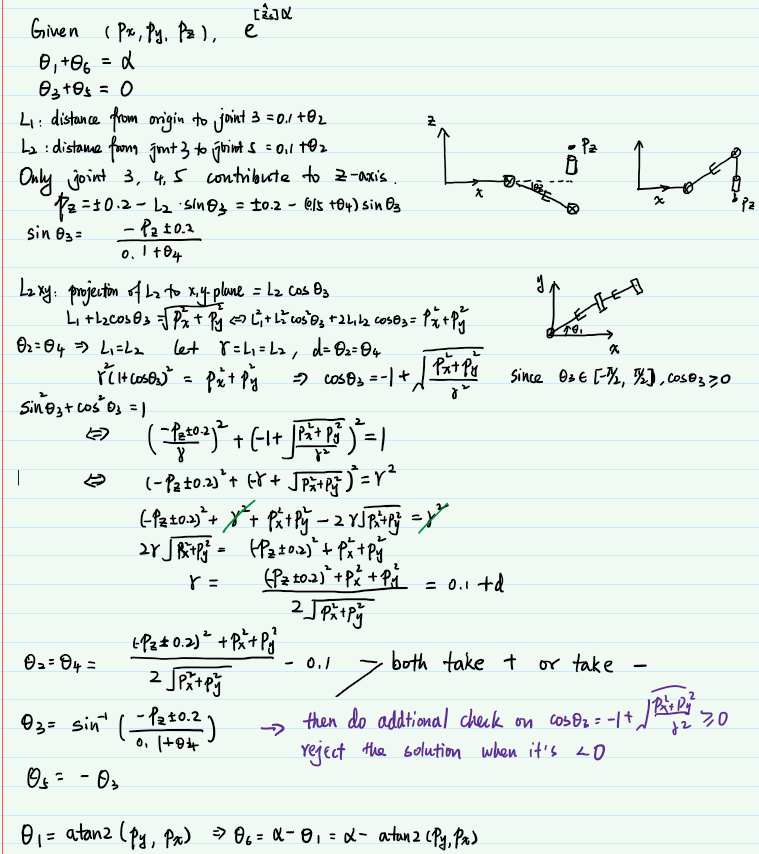

3. We favor the later one because at the zero position, the paddle has an offset above the xy-plane, so if we want to do elbow down, the prismatic joint will need to extend more, which may potentially break the joint limit. 

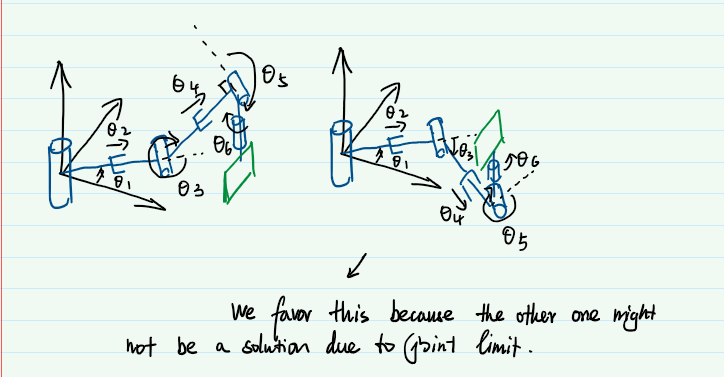

PartB:

- I copied the make_contact function from section2 and make it only return one value for T_sc. And then, I use the p_sb vector as the end effector coordinate, and follow the steps above to derive the inverse kinematics. I also added an additional check to check if the ball's position is within the task space. If it is not, then return an empty solution. 

             One thing to notice is that the end effector postion is not equal to the ball's position because of the volume of the ball. Therefore, I used the return value of make_contafct fucntion, and use the last column as the new vector/position of the end-effector to do the calculation.

               This function might be used in the future for calculating the trajectory or controller.

% Add the MATLAB library provided by http://modernrobotics.org
unzip('mr.zip');
ikFun = @inverse_kinematics;

% Constants:
% T_sh - home pose of the paddle (relative to the fixed frame)
R_sh = [0 0 1; 1 0 0; 0 1 0];
p_sh = [0.25; 0; 0.25];
T_sh = RpToTrans(R_sh, p_sh);

% Robot Design (copied from Section 3: Design)
% Define joint_types, joint_limits, B_list, S_list, and M
joint_types = ['R','P','R','P','R','R']; % the types of joints you have using a row vector of 'R' and 'P' elements
joint_limits = [[-pi/2;pi/2],[0;1],[-pi/2;pi/2],[0;1],[-pi;pi],[-pi;pi]]; % must have the dimensions [2, n_joints]
S_list = [[0;0;1;0;0;0],[0;0;0;1;0;0],[0;1;0;0;0;0.1],[0;0;0;1;0;0],[0;1;0;0;0;0.2],[0;0;1;0;-0.2;0]]; % must have the dimensions [6, n_joints] and each column must be a screw axis
B_list = [[0;1;0;0.2;0;0],[0;0;0;0;0;1],[1;0;0;0;-0.1;0.2],[0;0;0;0;0;1],[1;0;0;0;0;0.2],[0;1;0;0;0;0]]; % must have the dimensions [6, n_joints] and each column must be a screw axis
M = [[0,0,1,0.2];[1,0,0,0];[0,1,0,0.2];[0,0,0,1]]; % must be a 4x4 homogeneous transformation matrix (i.e., in SE(3))
n_joints = length(joint_types);

% Inputs
% p_sb - The position of the ball (in the fixed frame)
% Outputs
% T_sc - The desired contact pose of the paddle (in the fixed frame)
% solution_list - A matrix of all valid IK solutions where each row is a list of joint positions. Empty matrix if no valid solution found.

function [T_sc, solution_list] = inverse_kinematics(p_sb)
    % Generate a desired contact pose T_sc given the ball position p_sb
    % Hint: You can reuse parts of your make_contact function from Section 2: Task to help with this part
    % Note: You will need to choose a suitable paddle orientation for your robot
    contact_angle = 0
    [T_sc] = make_contact(p_sb, contact_angle)

    % Find all valid solutions of the IK problem for your robot to place the paddle in pose T_sc
    if any(p_sb > [1.1;0.8;0.7] | p_sb < [0.3;-0.8;-0.1])
        solution_list = [];
        return;
    end
        x = T_sc(1,4)
        y = T_sc(2,4)
        z = T_sc(3,4)
        theta1 = atan2(y, x)
        theta2_pos = ((-z + 0.2).^2 + x.^2 + y.^2) / (2 * sqrt(x.^2 + y.^2)) - 0.1
        theta3_pos = asin((-z + 0.2)/(0.1 + theta2_pos))
        
        if theta1 < -pi/2 || theta1 > pi/2 || theta3_pos < -pi/2 || theta3_pos > pi/2
            solution_list = [];
            return;
        end
        
        solution_list = [[theta1 theta2_pos theta3_pos theta2_pos -theta3_pos contact_angle-theta1]]; % Each row is a valid set of joint positions
end
function [T_sc] = make_contact(p_sb, theta)
% Inputs:
% p_sb - fixed ball position (relative to the fixed frame)
% theta - desired paddle contact angle about a vertical axis


% Constants:
% T_sh - home pose of the paddle (relative to the fixed frame)
R_sh = [0 0 1; 1 0 0; 0 1 0];
p_sh = [0.25; 0; 0.25];
T_sh = RpToTrans(R_sh, p_sh);


% Generate:
% p_hb - the position of the ball (relative to the home pose),
% T_sc - the contact pose (relative to the fixed frame), and
% T_hc - the motion required to move from the home pose to the contact pose.

p_hb = TransInv(T_sh) * [p_sb; 1];
p_hb = p_hb(1:3);
omg = [0; 1; 0] * theta; % Rotation about the z-axis by theta
so3mat = VecToso3(omg);  % Calculate the skew
R_hc = MatrixExp3(so3mat); % Calculate the exponential
offset = (R_hc * [0;0;1]) * 0.01;
p_hc = p_hb - offset; % 0.01m away from the ball
T_sc = T_sh * RpToTrans(R_hc, p_hc);
end


2. I copy and past codes from question 1 with some minor modifications. The inverse_kinematics now accepts two types of inputs: if the input is a vector, then we know this should be the ball position, so we do exactly the same as question 1, obtaining the T_sc and calculate. However, if the input is a matrix, then we use it as T_sc, and do not perform the out of task space check. This is because sometimes we do want to just move the paddle around but the destination of this might not be within the task space. E.g. move the paddle from its zero position (out side of the cuboid) into the cuboid.

Then, we simply use the build-in function to calculate the trajectory given the home and end configurations. We sample t_c * freq + 1 points since we want to include both the start and the end. 

This funciton can be useful in the future for the control of the robot.

% Add the MATLAB library provided by http://modernrobotics.org
unzip('mr.zip');
ikFun = @inverse_kinematics;
genTraj = @generate_trajectory;

% Constants:
% T_sh - home pose of the paddle (relative to the fixed frame)
R_sh = [0 1 0; 0 0 1; 1 0 0]';
p_sh = [0.25 0 0.25]';
T_sh = RpToTrans(R_sh, p_sh);

% Robot Design (copied from Section 3: Design)
% Define joint_types, joint_limits, B_list, S_list, and M
joint_types = ['R','P','R','P','R','R']; % the types of joints you have using a row vector of 'R' and 'P' elements
joint_limits = [[-pi/2;pi/2],[0;1],[-pi/2;pi/2],[0;1],[-pi;pi],[-pi;pi]]; % must have the dimensions [2, n_joints]
S_list = [[0;0;1;0;0;0],[0;0;0;1;0;0],[0;1;0;0;0;0.1],[0;0;0;1;0;0],[0;1;0;0;0;0.2],[0;0;1;0;-0.2;0]]; % must have the dimensions [6, n_joints] and each column must be a screw axis
B_list = [[0;1;0;0.2;0;0],[0;0;0;0;0;1],[1;0;0;0;-0.1;0.2],[0;0;0;0;0;1],[1;0;0;0;0;0.2],[0;1;0;0;0;0]]; % must have the dimensions [6, n_joints] and each column must be a screw axis
M = [[0,0,1,0.2];[1,0,0,0];[0,1,0,0.2];[0,0,0,1]]; % must be a 4x4 homogeneous transformation matrix (i.e., in SE(3))
speed_limits(joint_types == 'P') = 0.5;
speed_limits(joint_types == 'R') = 2.0;
n_joints = length(joint_types);

% Inverse Kinematics function (copied from the IK problem in Section 4: Validation)
% NOTE: This function has been modified so you can pass it p_sb *or* T_sc
% Inputs
% p_sb - The position of the ball (in the fixed frame)
% OR
% T_sc - The desired contact pose of the paddle (in the fixed frame)
% Outputs
% T_sc - The desired contact pose of the paddle (in the fixed frame)
% solution_list - A matrix of all valid IK solutions where each row is a list of joint positions. Empty matrix if no valid solution found.
function [T_sc, solution_list] = inverse_kinematics(var)
if size(var)==[4 4] & TestIfSE3(var)
    % The input variable is in SE(3), so set T_sc to the input
    T_sc = var;
else
    % The input variable is not in SE(3), so set p_sb to the input
    p_sb = reshape(var,[3,1]);

    % Generate a desired contact pose T_sc given the ball position p_sb
    % Note: Copy this section from the IK problem in Section 4: Validation
    contact_angle = 0;
    [T_sc] = make_contact(p_sb, contact_angle);
end

% Find all valid solutions of the IK problem for your robot to place the paddle in pose T_sc
% Note: Copy this section from the IK problem in Section 4: Validation
% Note: If T_sc is provided, it may be the home pose outside the cuboid
% If pass a home pose, then never return empty list because of out of cuboid
if size(var)==[4 4] & TestIfSE3(var)
    contact_angle = 0;
    p_sb = var(1:3,4);
elseif any(p_sb > [1.1;0.8;0.7] | p_sb < [0.3;-0.8;-0.1])
    solution_list = [];
    return;
end

x = T_sc(1,4);
y = T_sc(2,4);
z = T_sc(3,4);
theta1 = atan2(y, x);
theta2_pos = ((-z + 0.2).^2 + x.^2 + y.^2) / (2 * sqrt(x.^2 + y.^2)) - 0.1;
theta3_pos = asin((-z + 0.2)/(0.1 + theta2_pos));

solution_list = [[theta1 theta2_pos theta3_pos theta2_pos -theta3_pos contact_angle-theta1]]; % Each row is a valid set of joint positions
end

% Inputs
% p_sb - The position of the ball at time tc (in the fixed frame)
% t_c - The time at which the ball will be at p_sb
% freq - The sampling frequency (in Hz) used to generate your trajectory
% Outputs
% joint_traj - A matrix defining a joint trajectory were each row is a set of joint positions. Empty matrix if no solution found.
function joint_traj = generate_trajectory(p_sb, t_c, freq)
    % Find all valid configurations which contact the ball at p_sb
    [~, goal_configs] = inverse_kinematics(p_sb)
    if isempty(goal_configs)
        joint_traj = [];
        return;
    end
    
    % Find all valid home configurations
    T_sh = RpToTrans([0 1 0; 0 0 1; 1 0 0]', [0.25 0 0.25]');
    [~, home_configs] = inverse_kinematics(T_sh);

% Find a valid trajectory for your robot to follow to end up with the paddle at rest in pose T_sc at or before t_c
    N = t_c * freq;
    joint_traj = JointTrajectory(home_configs',goal_configs',t_c,N + 1,3)
    %joint_traj = [home; ...; goal]; % Each row is a valid set of joint positions
    %joint_traj = []; % If no valid trajectory is found, then return an empty matrix

end

function [T_sc] = make_contact(p_sb, theta)
% Inputs:
% p_sb - fixed ball position (relative to the fixed frame)
% theta - desired paddle contact angle about a vertical axis

% Constants:
% T_sh - home pose of the paddle (relative to the fixed frame)
R_sh = [0 0 1; 1 0 0; 0 1 0];
p_sh = [0.25; 0; 0.25];
T_sh = RpToTrans(R_sh, p_sh);

% Generate:
% p_hb - the position of the ball (relative to the home pose),
% T_sc - the contact pose (relative to the fixed frame), and
% T_hc - the motion required to move from the home pose to the contact pose.

p_hb = TransInv(T_sh) * [p_sb; 1];
p_hb = p_hb(1:3);
omg = [0; 1; 0] * theta; % Rotation about the z-axis by theta
so3mat = VecToso3(omg);  % Calculate the skew
R_hc = MatrixExp3(so3mat); % Calculate the exponential
offset = (R_hc * [0;0;1]) * 0.01;
p_hc = p_hb - offset; % 0.01m away from the ball
T_sc = T_sh * RpToTrans(R_hc, p_hc);
end